# Mapping + Route selection



clc
clear
close all

% Get coordinates of Mawson Station
Mawson_coords = scarloc('mawson station');
Spatial_res = 10;
% Create a map centered on Mawson Station
figure;
figure('Position', [100, 100, 1200, 800]);
mapzoomps(Mawson_coords(1), Mawson_coords(2), 'size', [100 100], 'frame', 'off','km');
hold on;
scatterps(Mawson_coords(1), Mawson_coords(2), 10,'Marker', 'd', 'MarkerFaceColor', 'r');
scarlabel('Mawson Station');
title('Step 1: Select the waypoints along the route');
% Customize the plot as needed
box on;
scalebarps;

[bed,lat,lon] = bedmachine_data('bed',xlim,ylim,'geo');
pcolorps(lat,lon,bed);
bedmachine('surface', 'contour', 0:100:5000);
colorbar;
% Get waypoints interactively
disp('Select waypoints on the map. Press enter when done :)');

Select waypoints on the map. Press enter when done :)


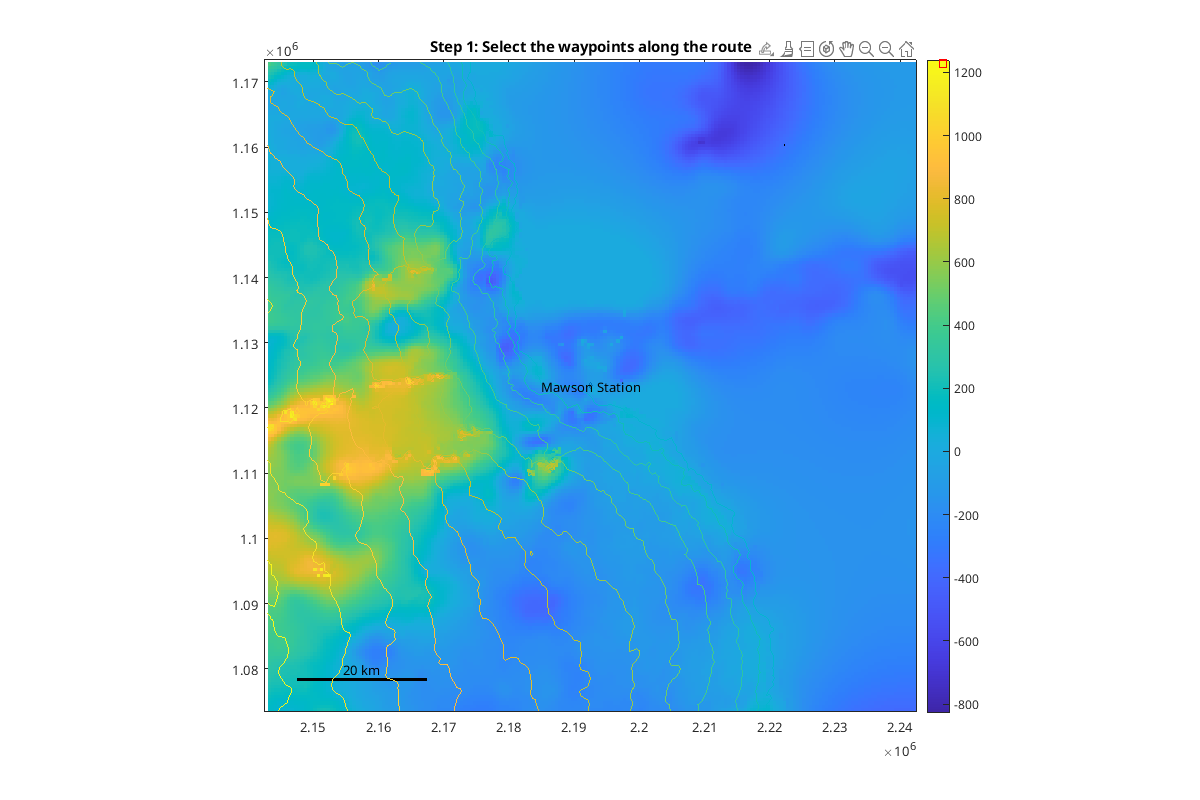

[lat,lon] = coord;

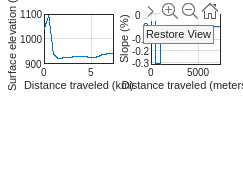

% Assign start and end points
startlat = lat(1);
startlon = lon(1);
endlat = lat(end);
endlon = lon(end);
intermediatewaypoints = [lat(2:end-1) lon(2:end-1)];
waypoints = [startlat startlon; intermediatewaypoints; endlat endlon];
[lati,loni] = pspath([startlat endlat],[startlon endlon],Spatial_res);  %gives interpolated points between the specified waypoints
linpath = [lati ; loni]';       
path = [startlat,startlon];

% Initialize cell arrays to store latitude and longitude
path_lat = startlat;
path_lon = startlon;

for k = 1:height(waypoints)
    if k < height(waypoints)
        [interlat, interlon] = pspath([waypoints(k,1) waypoints(k+1,1)], [waypoints(k,2) waypoints(k+1,2)], Spatial_res);
        
        % Append new latitude and longitude values
        path_lat = [path_lat; interlat'];
        path_lon = [path_lon; interlon'];
    end
end

% Concatenate latitude and longitude arrays
path = [path_lat, path_lon];

d = pathdistps(path(:,1)', path(:,2)', 'km')';
z = bedmachine_interp('surface', path(:,1)', path(:,2)')';
figure;
% Subplot 2: Plot of Distance traveled vs Surface elevation
subplot(2,2,1);
plot(d, z)
xlabel 'Distance traveled (km)'
ylabel 'Surface elevation (m)'
grid on

% Convert distance to meters
d_meters = d*1000;  % Convert kilometers to meters

%envdata=ncdataset('env_data.grib')

% Subplot 3: Plot of Slope vs Distance traveled
subplot(2, 2, 2);

% Calculate slope (gradient) using finite differences
dz = diff(z);  % Calculate difference in elevation
dd = diff(d_meters);  % Calculate difference in distance (in meters)
slope = dz ./ dd;  % Calculate slope

% Plot the slope
plot(d_meters(2:end), slope)
xlabel 'Distance traveled (meters)'
ylabel 'Slope (%)'
grid on

## Slicer function 

clc
close all

% Subplot 4: Interactive Elevation Profile Slicer
figure
plot(d_meters, z)
xlabel 'Distance traveled (meters)'
ylabel 'Surface elevation (m)'
grid on

title('Step 2: Interactive elevation profile slicer');
disp('Select slicepoints on the plot. Right-click when done :)');

Select slicepoints on the plot. Right-click when done :)


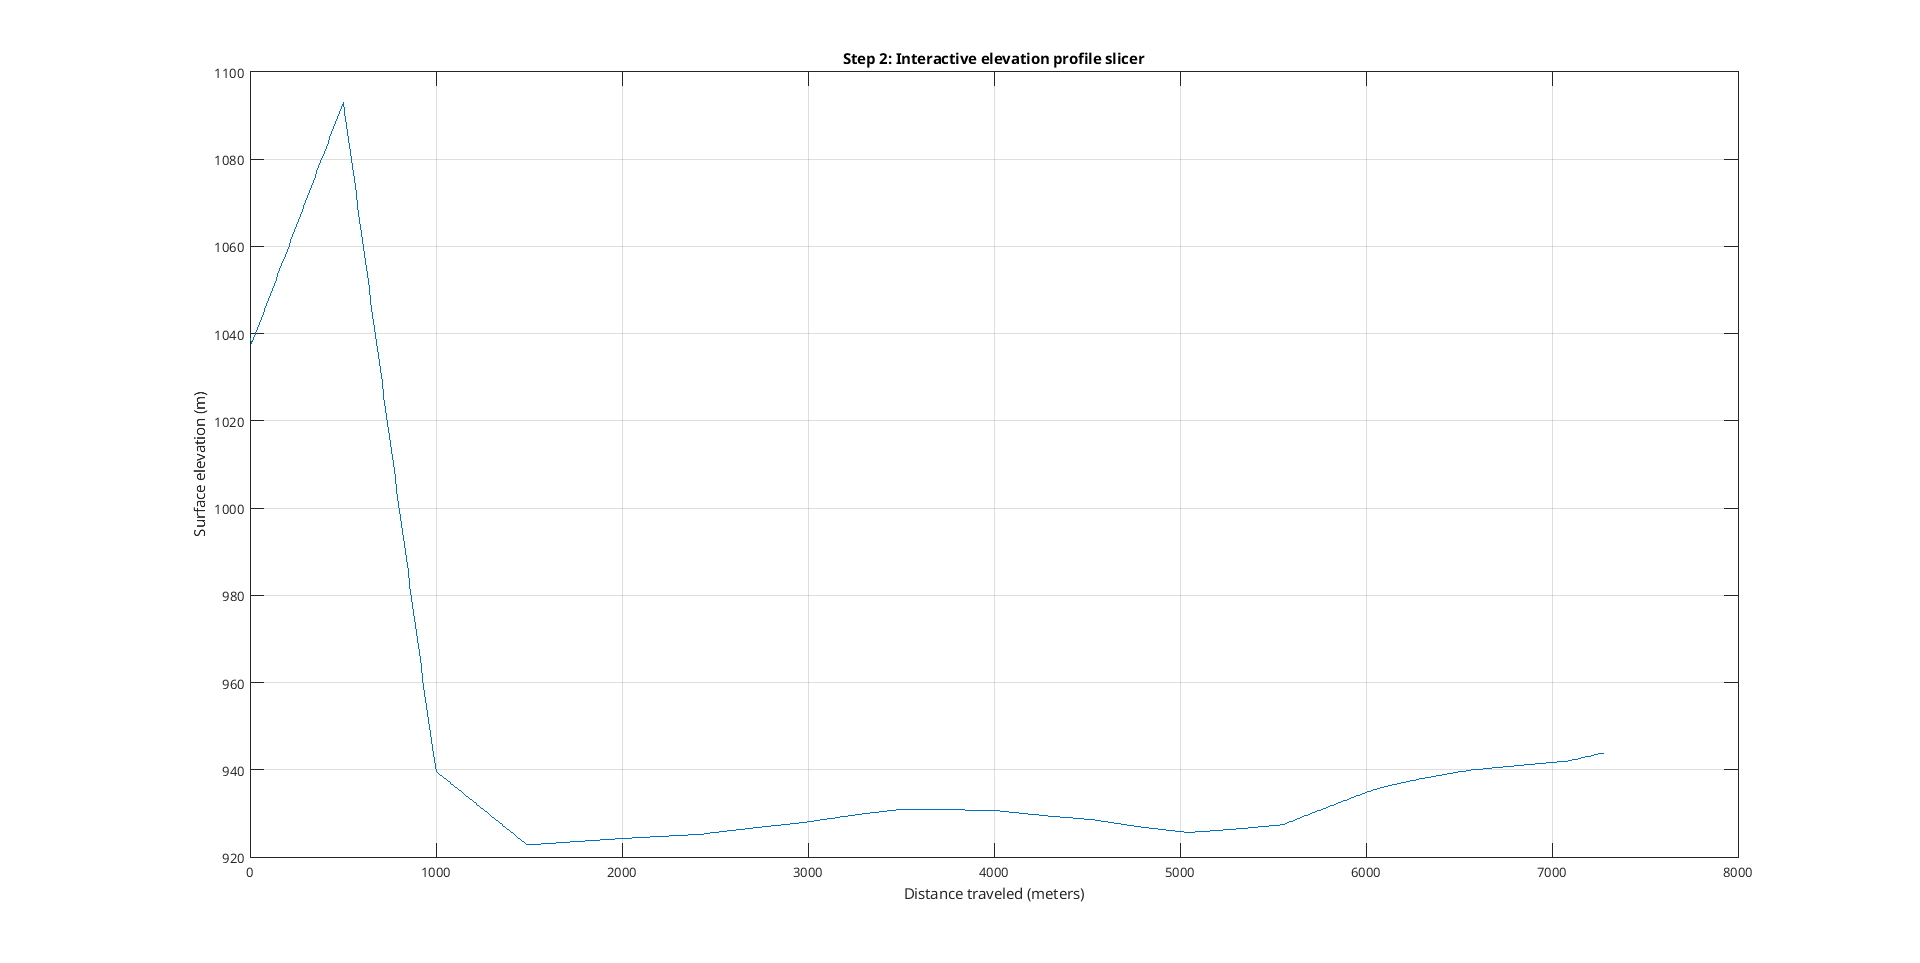

[slicepoints_x, ~] = ginput();

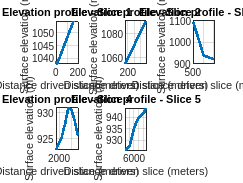

endslice_x = d_meters(end);
endslice_y = z(end);

num_slices = length(slicepoints_x) + 1;

% Calculate the number of rows and columns for the subplot grid
cols = ceil(sqrt(num_slices));
rows = ceil(num_slices / cols);

% Create a figure with a subplot grid
figure

for i = 1:num_slices
    if i == 1
        % For the first slice, start from the real distance
        start_distance = 0;
    else
        % For subsequent slices, start from the end of the previous slice
        start_distance = slice_d(end);
    end
    
    % Handle the last slice differently
    if i == num_slices
        end_distance = endslice_x;
    else
        end_distance = slicepoints_x(i);
    end
    
    % Find indices corresponding to the selected slice
    [~, start_index] = min(abs(d_meters - start_distance));
    [~, end_index] = min(abs(d_meters - end_distance));

    % Extract the elevation and distance data for the slice
    slice_d = d_meters(start_index:end_index);
    slice_z = z(start_index:end_index);

    % adjust distance to start from the real distance
    slice_d = slice_d - slice_d(1) + start_distance;

    % calculate the subplot index based on the current iteration
     subplot(rows, cols, i);
    plot(slice_d, slice_z, 'LineWidth', 2);
    xlabel 'Distance driven slice (meters)'
    ylabel 'Surface elevation (m)'
    title(['Elevation profile - Slice ', num2str(i)]);
    grid on
end